# Estudio de los **grados**, la** entropia** y de la **centralidad** 

Importo: 

load("MatricesSparse.mat")
max_pais = [1920 3413 6248 8841 9088];

Los siguientes valores son la dimension de los arrays autores1, autores2, etc... de Cosas_Previas_Archivo1_TFG. Se emplean para la degree distribution de cada pais.

autoresF = 1907;% = sum(cont_grados_Colab_F_S)
autoresE = 1489;
autoresA = 2815;
autoresI = 2586;
autoresP = 246;
% sum(cont_grados_Colab_S)=9043=autoresF+autoresE+autoresA+autoresI+autoresP

Cargo las carpetas del directorio al path

addpath(genpath("D:\## DOCUMENTOS ##\UCM\TFG"))

## **GRADOS**

Las siguientes funciones estan hechas con las matrices 9088x9088 *Colab_PAIS_S, *no con las matrices "acotadas" *Pais_Colab *pero el resultado es el mismo en ambos casos.

## Degree Distribution de Colab_S == Probability Degree k Function pdf(k) 

Primero calculo el grado de cada nodo de la matriz Colab_S.

grados_Colab_S = zeros(size(Colab_S,1),1);
for i = 1:size(Colab_S,1)
    grados_Colab_S(i) = sum(Colab_S(i,:));
end

Ahora cuento cuantos nodos tienen grado 1, 2, etc... y calculo el Degree Distribution (by counting how many nodes have each degree, we form the degree distribution = fraction of nodes in the graph with degree k.)

cont_grados_Colab_S = zeros(max(grados_Colab_S),1);
for i = 1:length(grados_Colab_S)
    if grados_Colab_S(i) ~= 0
        grados_Colab_S(i) = int64(grados_Colab_S(i));
        cont_grados_Colab_S(grados_Colab_S(i)) = cont_grados_Colab_S(grados_Colab_S(i)) + 1;
    end
end
clf
DegDtbn_Colab_S = cont_grados_Colab_S/sum(cont_grados_Colab_S); %Dividido entre el total de nodos no nulos 9043
grado_media = mean(grados_Colab_S) % Grado medio de los nodos

grado_media = 13.4003

grado_mediana = median(grados_Colab_S) % Mediana de los grados de los nodos

grado_mediana = 9

grado_cuantil = quantile(grados_Colab_S,[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

grado_cuantil =     2.9000    6.0000    9.0000   15.0000   53.0000


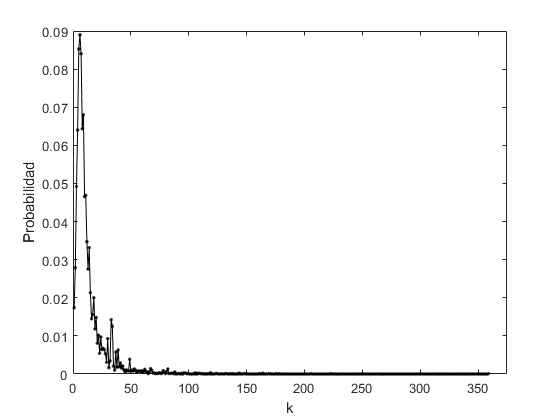

%Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_S,'NumBins',150,'FaceColor','k')
% xlabel('Apariciones del grado k')
% ylabel('Total de grados con x apariciones')
% %Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_S),'NumBins',110,'FaceColor','k')
% xlabel('log(Apariciones del grado k)')
% ylabel('log(Total de grados con x apariciones)')
%Grafica del Degree Distribution
plot(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
xlim([0 375])
xlabel('k')
ylabel('Probabilidad')

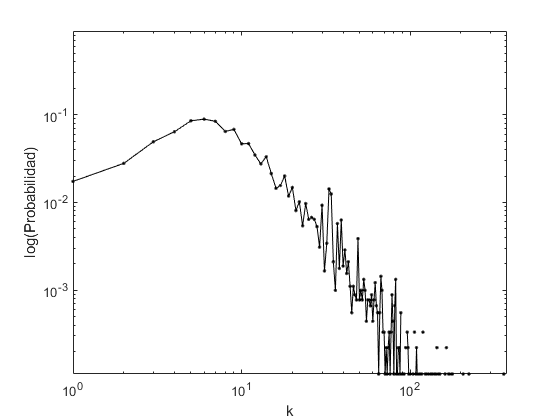

%Grafica del Degree Distribution escala logaritmica
loglog(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
xlabel('k')
ylabel('log(Probabilidad)')
axis([0 375 -1 0.9])

%axis([0 log10(365) -1e4 0])

Conclusiones de lo graficado:

- Mediante el **histograma** observamos que la gran mayoria de los 359 posibles grados aparecen pocas veces, menos de 25 veces. Y vemos que hay ciertos grados que aparecen 600 y casi 800 veces.  

- En el histograma en escala logaritmica se ve mas recogidito porque el log(800)~7

- Despues observamos la grafica de la distribucion de los grados donde se observa que los grados bajos son mucho mas frecuentes que grados superiores a 30

## Degree Distribution de Colab_F_S

Todo el proceso de golpe.

grados_Colab_F_S = zeros(size(Colab_F_S,1),1);
for i = 1:size(Colab_F_S,1)
    grados_Colab_F_S(i) = sum(Colab_F_S(i,:));
end
cont_grados_Colab_F_S = zeros(max(grados_Colab_F_S),1);
for i = 1:length(grados_Colab_F_S)
    if grados_Colab_F_S(i) ~= 0
        grados_Colab_F_S(i) = int64(grados_Colab_F_S(i));
        cont_grados_Colab_F_S(grados_Colab_F_S(i)) = cont_grados_Colab_F_S(grados_Colab_F_S(i)) + 1;
    end
end
DegDtbn_Colab_F_S = cont_grados_Colab_F_S/autoresF;
gradoF_media = mean(grados_Colab_F_S(1:1920)) % Grado medio de los nodos

gradoF_media = 13.7479

gradoF_mediana = median(grados_Colab_F_S(1:1920)) % Mediana de los grados de los nodos

gradoF_mediana = 9

gradoF_cuantil = quantile(grados_Colab_F_S(1:1920),[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

gradoF_cuantil =     2.0000    6.0000    9.0000   15.0000   57.5000


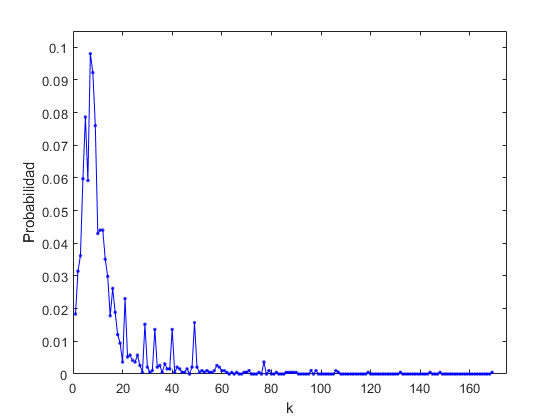

% Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_F_S,'NumBins',90,'FaceColor','b')
% xlabel('Apariciones del grado')
% ylabel('Total de grados con x apariciones')
% % Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_F_S),'NumBins',90,'FaceColor','b')
% xlabel('log(Apariciones del grado)')
% ylabel('log(Total de grados con x apariciones)')
% Grafica del Degree Distribution FRANCIA
plot(1:max(grados_Colab_F_S),DegDtbn_Colab_F_S,'b.-')
axis([0 175 0 0.105])
xlabel('k')
ylabel('Probabilidad')

Conclusiones de lo graficado:

- (Para los paises no hago aqui este apartado)

## Degree Distribution de Colab_E_S

Todo el proceso de golpe.

grados_Colab_E_S = zeros(size(Colab_E_S,1),1);
for i = 1:size(Colab_E_S,1)
    grados_Colab_E_S(i) = sum(Colab_E_S(i,:));
end
cont_grados_Colab_E_S = zeros(max(grados_Colab_E_S),1);
for i = 1:length(grados_Colab_E_S)
    if grados_Colab_E_S(i) ~= 0
        grados_Colab_E_S(i) = int64(grados_Colab_E_S(i));
        cont_grados_Colab_E_S(grados_Colab_E_S(i)) = cont_grados_Colab_E_S(grados_Colab_E_S(i)) + 1;
    end
end
DegDtbn_Colab_E_S = cont_grados_Colab_E_S/autoresE;
gradoE_media = mean(grados_Colab_E_S(1920:3413)) % Grado medio de los nodos

gradoE_media = 10.9438

gradoE_mediana = median(grados_Colab_E_S(1920:3413)) % Mediana de los grados de los nodos

gradoE_mediana = 8

gradoE_cuantil = quantile(grados_Colab_E_S(1920:3413),[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

gradoE_cuantil =      2     5     8    13    39


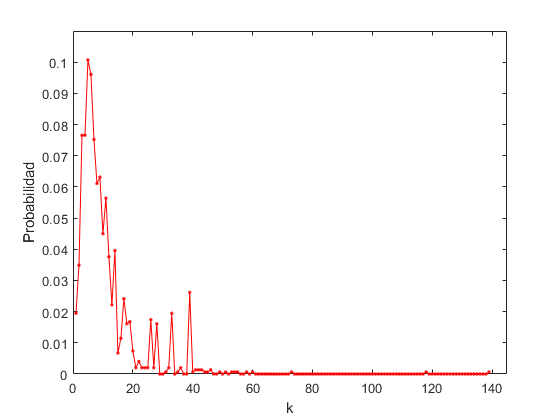

% Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_E_S,'NumBins',70,'FaceColor','r')
% xlabel('Apariciones del grado')
% ylabel('Total de grados con x apariciones')
% % Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_E_S),'NumBins',60,'FaceColor','r')
% axis([-0.1 2.25 0 16])
% xlabel('log(Apariciones del grado)')
% ylabel('log(Total de grados con x apariciones)')
%Grafica del Degree Distribution ESPAÑA
plot(1:max(grados_Colab_E_S),DegDtbn_Colab_E_S,'r.-')
axis([0 145 0 0.11])
xlabel('k')
ylabel('Probabilidad')

Conclusiones de lo graficado:

- (Para los paises no hago aqui este apartado)

## Degree Distribution de Colab_A_S

Todo el proceso de golpe.

grados_Colab_A_S = zeros(size(Colab_A_S,1),1);
for i = 1:size(Colab_A_S,1)
    grados_Colab_A_S(i) = sum(Colab_A_S(i,:));
end
cont_grados_Colab_A_S = zeros(max(grados_Colab_A_S),1);
for i = 1:length(grados_Colab_A_S)
    if grados_Colab_A_S(i) ~= 0
        grados_Colab_A_S(i) = int64(grados_Colab_A_S(i));
        cont_grados_Colab_A_S(grados_Colab_A_S(i)) = cont_grados_Colab_A_S(grados_Colab_A_S(i)) + 1;
    end
end
DegDtbn_Colab_A_S = cont_grados_Colab_A_S/autoresA;
gradoA_media = mean(grados_Colab_A_S(3413:6248)) % Grado medio de los nodos

gradoA_media = 15.6269

gradoA_mediana = median(grados_Colab_A_S(3413:6248)) % Mediana de los grados de los nodos

gradoA_mediana = 10

gradoA_cuantil = quantile(grados_Colab_A_S(3413:6248),[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

gradoA_cuantil =     2.0000    5.5000   10.0000   19.0000   67.0000


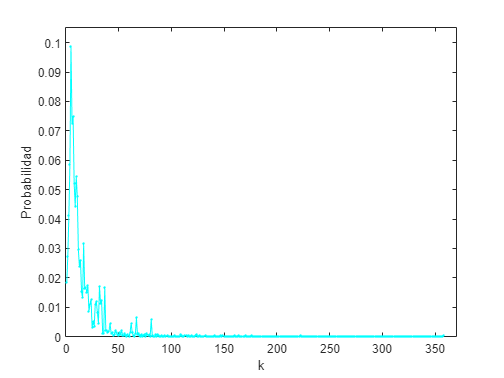

% Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_A_S,'NumBins',90,'FaceColor','c')
% xlabel('Apariciones del grado')
% ylabel('Total de grados con x apariciones')
% % Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_A_S),'NumBins',70,'FaceColor','c')
% xlabel('log(Apariciones del grado)')
% ylabel('log(Total de grados con x apariciones)')
%Grafica del Degree Distribution ALEMANIA
plot(1:max(grados_Colab_A_S),DegDtbn_Colab_A_S,'c.-')
axis([0 370 0 0.105])
xlabel('k')
ylabel('Probabilidad')

Conclusiones de lo graficado:

- (Para los paises no hago aqui este apartado)

## Degree Distribution de Colab_I_S

Todo el proceso de golpe.

grados_Colab_I_S = zeros(size(Colab_I_S,1),1);
for i = 1:size(Colab_I_S,1)
    grados_Colab_I_S(i) = sum(Colab_I_S(i,:));
end
cont_grados_Colab_I_S = zeros(max(grados_Colab_I_S),1);
for i = 1:length(grados_Colab_I_S)
    if grados_Colab_I_S(i) ~= 0
        grados_Colab_I_S(i) = int64(grados_Colab_I_S(i));
        cont_grados_Colab_I_S(grados_Colab_I_S(i)) = cont_grados_Colab_I_S(grados_Colab_I_S(i)) + 1;
    end
end
DegDtbn_Colab_I_S = cont_grados_Colab_I_S/autoresI;
gradoP_media = mean(grados_Colab_I_S(6248:8841)) % Grado medio de los nodos

gradoP_media = 12.1203

gradoP_mediana = median(grados_Colab_I_S(6248:8841)) % Mediana de los grados de los nodos

gradoP_mediana = 8

gradoP_cuantil = quantile(grados_Colab_I_S(6248:8841),[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

gradoP_cuantil =      3     6     8    14    43


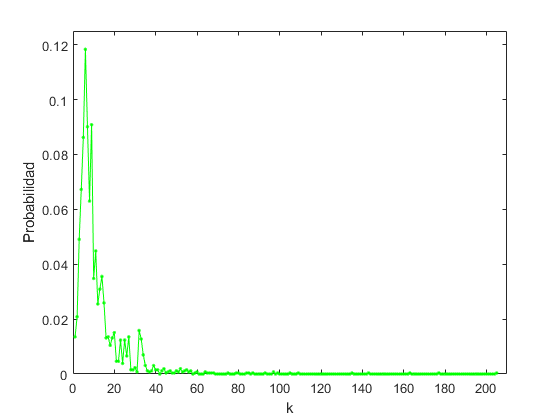

% Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_I_S,'NumBins',70,'FaceColor','g')
% xlabel('Apariciones del grado')
% ylabel('Total de grados con x apariciones')
% % Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_I_S),'NumBins',70,'FaceColor','g')
% xlabel('log(Apariciones del grado)')
% ylabel('log(Total de grados con x apariciones)')
%Grafica del Degree Distribution ITALIA
plot(1:max(grados_Colab_I_S),DegDtbn_Colab_I_S,'g.-')
axis([0 210 0 0.125])
xlabel('k')
ylabel('Probabilidad')

Conclusiones de lo graficado:

- (Para los paises no hago aqui este apartado)

## Degree Distribution de Colab_P_S

Todo el proceso de golpe.

grados_Colab_P_S = zeros(size(Colab_P_S,1),1);
for i = 1:size(Colab_P_S,1)
    grados_Colab_P_S(i) = sum(Colab_P_S(i,:));
end
cont_grados_Colab_P_S = zeros(max(grados_Colab_P_S),1);
for i = 1:length(grados_Colab_P_S)
    if grados_Colab_P_S(i) ~= 0
        grados_Colab_P_S(i) = int64(grados_Colab_P_S(i));
        cont_grados_Colab_P_S(grados_Colab_P_S(i)) = cont_grados_Colab_P_S(grados_Colab_P_S(i)) + 1;
    end
end
DegDtbn_Colab_P_S = cont_grados_Colab_P_S/autoresP;
gradoP_media = mean(grados_Colab_P_S(8841:9088)) % Grado medio de los nodos

gradoP_media = 9.0242

gradoP_mediana = median(grados_Colab_P_S(8841:9088)) % Mediana de los grados de los nodos

gradoP_mediana = 9

gradoP_cuantil = quantile(grados_Colab_P_S(8841:9088),[0.05 0.25 0.5 0.75 0.975]) % Cuantiles de los grados de los nodos

gradoP_cuantil =      2     5     9    13    19


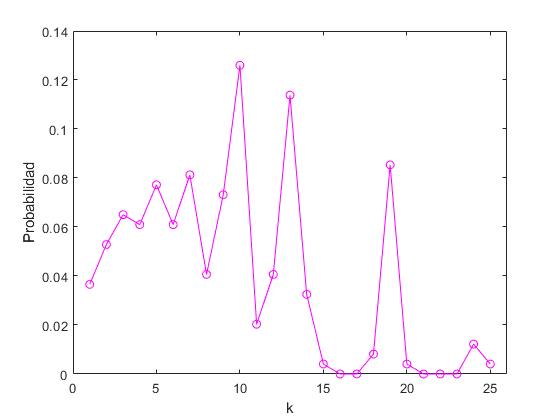

% Histograma de cuantas veces aparece cada grado
% histogram(cont_grados_Colab_P_S,'NumBins',45,'FaceColor','m')
% axis([-1 32 0 5.5])
% xlabel('Apariciones del grado')
% ylabel('Total de grados con x apariciones')
% % Histograma de cuantas veces aparece cada grado en escala logaritmica
% histogram(log10(cont_grados_Colab_P_S),'NumBins',45,'FaceColor','m')
% axis([-0.1 1.6 0 3.5])
% xlabel('log(Apariciones del grado)')
% ylabel('log(Total de grados con x apariciones)')
%Grafica del Degree Distribution PORTUGAL
plot(1:max(grados_Colab_P_S),DegDtbn_Colab_P_S,'mo-') %COmo son pocos pongo este otro marker mas vistoso
axis([0 26 0 0.14])
xlabel('k')
ylabel('Probabilidad')

Conclusiones de lo graficado:

- (Para los paises no hago aqui este apartado)

## GRAFICOS "MANO A MANO"

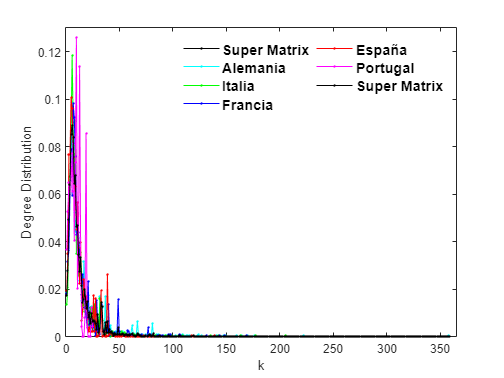

figure
plot(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
hold on
plot(1:max(grados_Colab_A_S),DegDtbn_Colab_A_S,'c.-')
plot(1:max(grados_Colab_I_S),DegDtbn_Colab_I_S,'g.-')
plot(1:max(grados_Colab_F_S),DegDtbn_Colab_F_S,'b.-')
plot(1:max(grados_Colab_E_S),DegDtbn_Colab_E_S,'r.-')
plot(1:max(grados_Colab_P_S),DegDtbn_Colab_P_S,'m.-') 
plot(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('Degree Distribution')
legend({'Super Matrix','Alemania','Italia','Francia','España','Portugal','Super Matrix'},...
    'Location','northeast','NumColumns',2,'Box','off','FontWeight','bold','FontSize',12);
hold off

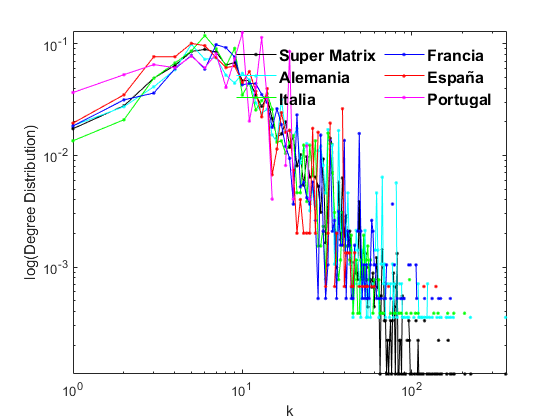


figure
loglog(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
hold on
loglog(1:max(grados_Colab_A_S),DegDtbn_Colab_A_S,'c.-')
loglog(1:max(grados_Colab_I_S),DegDtbn_Colab_I_S,'g.-')
loglog(1:max(grados_Colab_F_S),DegDtbn_Colab_F_S,'b.-')
loglog(1:max(grados_Colab_E_S),DegDtbn_Colab_E_S,'r.-')
loglog(1:max(grados_Colab_P_S),DegDtbn_Colab_P_S,'m.-') 
axis([0 365 0 0.13])
set(gca,"xscale","log","yscale","log"); %"linear" "log"
xlabel('k')
ylabel('log(Degree Distribution)')
legend({'Super Matrix','Alemania','Italia','Francia','España','Portugal'},...
    'Location','northeast','NumColumns',2,'Box','off','FontWeight','bold','FontSize',12);
hold off

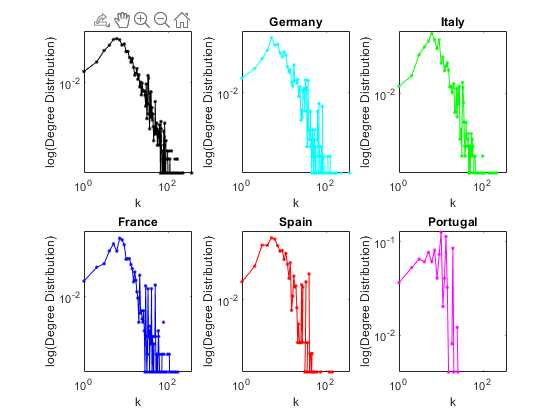


figure
subplot(2,3,1)
loglog(1:max(grados_Colab_S),DegDtbn_Colab_S,'k.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('Super Matrix')

subplot(2,3,2)
loglog(1:max(grados_Colab_A_S),DegDtbn_Colab_A_S,'c.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('Germany')

subplot(2,3,3)
loglog(1:max(grados_Colab_I_S),DegDtbn_Colab_I_S,'g.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('Italy')

subplot(2,3,4)
loglog(1:max(grados_Colab_F_S),DegDtbn_Colab_F_S,'b.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('France')

subplot(2,3,5)
loglog(1:max(grados_Colab_E_S),DegDtbn_Colab_E_S,'r.-')
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('Spain')

subplot(2,3,6)
loglog(1:max(grados_Colab_P_S),DegDtbn_Colab_P_S,'m.-') 
axis([0 365 0 0.13])
xlabel('k')
ylabel('log(Degree Distribution)')
title('Portugal')

## Cumulative Degree k Function de Colab_S, cdf(k) 

**PROBABILIDAD DE TENER GRADO MENOR O IGUAL**

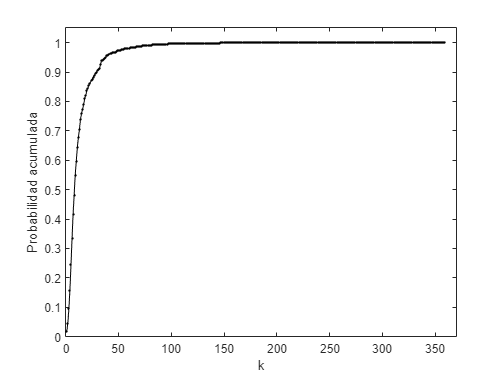

clf
cdf_Colab_S = zeros(max(grados_Colab_S),1);
cdf_Colab_S(1) = DegDtbn_Colab_S(1);
for i = 2:length(DegDtbn_Colab_S)
    cdf_Colab_S(i) = cdf_Colab_S(i-1) + DegDtbn_Colab_S(i);
end
%Grafica del Cumulative Degree Distribution
figure
plot(1:max(grados_Colab_S),cdf_Colab_S,'k.-')
axis([0 370 0 1.05])
xlabel('k')
ylabel('Probabilidad acumulada')

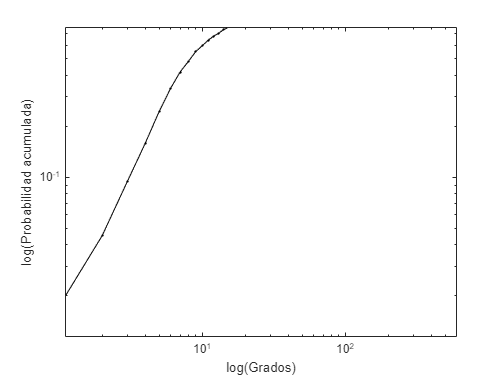

figure
loglog(1:max(grados_Colab_S),cdf_Colab_S,'k.-')
xlabel('log(Grados)')
ylabel('log(Probabilidad acumulada)')

Para saber el cdf de un grado k, es decir, cdf(k) se escribe cdf_Colab_S(k) que nos da la probabilidad de tener un grado menor o igual que k. Por ejemplo:

cdf_Colab_S(35)

ans = 0.9407

**PROBABILIDAD DE TENER GRADO MAYOR O IGUAL**

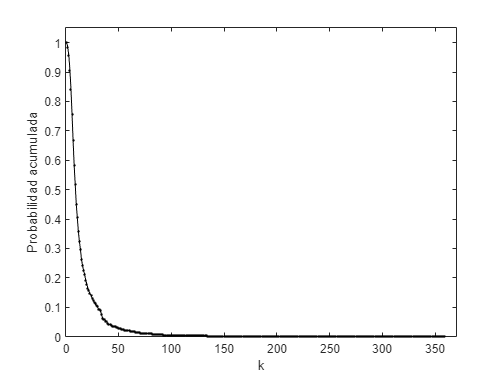

cdf_Colab_S_MAYOR = zeros(max(grados_Colab_S),1);
cdf_Colab_S_MAYOR(end) = DegDtbn_Colab_S(end);
for i = (length(DegDtbn_Colab_S)-1):-1:1
    cdf_Colab_S_MAYOR(i) = cdf_Colab_S_MAYOR(i+1) + DegDtbn_Colab_S(i);
end
%Grafica del Cumulative Degree Distribution
figure
plot(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k.-')
axis([0 370 0 1.05])
xlabel('k')
ylabel('Probabilidad acumulada')

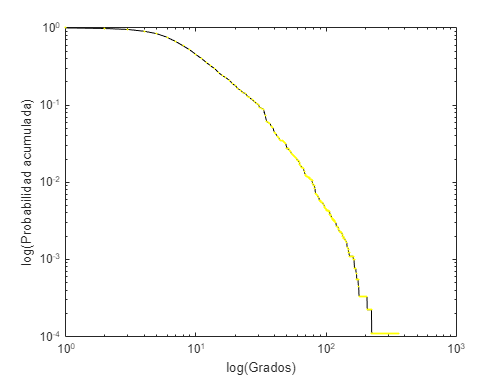

figure
loglog(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k')
hold on
loglog(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'y.','MarkerSize',5)
xlabel('log(Grados)')
ylabel('log(Probabilidad acumulada)')
hold off

## **CALCULO DE LOS GAMMA DE LAS SCALE-FREE**

Scale-free Network

**pdf(K)~=K^(-gamma) ¿Averiguar el gamma?:**

log10(pdf(k)) ~= -gamma*log10(K) + b  (Siendo b un numero real)

Sea y=log10(pdf(k)) y x=log(K), entonces y=-gamma*x+b Hay que averiguar el gamma y la b mediante una regresion lineal

#### Paso 1: Obtener las cummulative distributions cdf(k) MAYOR O IGUAL y pasarla a escala logaritmica

                                        log10( P(x>=K) ) 

cdf_Colab_S_MAYOR = zeros(max(grados_Colab_S),1);
logcdf_Colab_S_MAYOR = zeros(max(grados_Colab_S),1);
cdf_Colab_S_MAYOR(end) = DegDtbn_Colab_S(end);
for i = (length(DegDtbn_Colab_S)-1):-1:1
    cdf_Colab_S_MAYOR(i) = cdf_Colab_S_MAYOR(i+1) + DegDtbn_Colab_S(i);
    logcdf_Colab_S_MAYOR(i) = log10(cdf_Colab_S_MAYOR(i));
end
% Los grados tambien a escala logaritmica
x = transpose(log10(1:max(grados_Colab_S)));
% Simplificamos la notacion
y = logcdf_Colab_S_MAYOR;

#### Paso 2: Calculamos *y*=*β*0+*β*1*x *con *β*0=b y *β*1= - gamma

%format long
reg = polyfit(x,y,1);
yCalc = reg(1)*x + reg(2);
gamma_S = -reg(1)

gamma_S = 2.5208

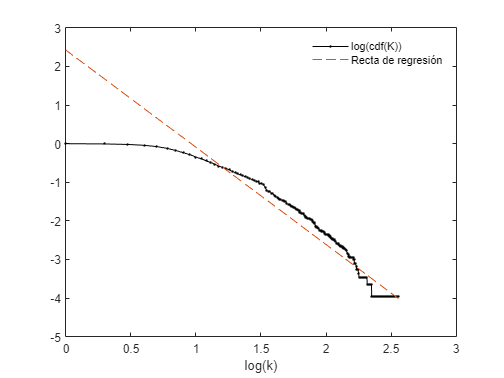

extra_S = reg(2);

figure
plot(log10(1:max(grados_Colab_S)),log10(cdf_Colab_S_MAYOR),'k.-')
%loglog(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k.-') %Con esto se
%descuadra el scale del siguiente plot
hold on
% scatter(x,y)
plot(x,yCalc,'--')
xlabel('log(k)')
legend({'log(cdf(K))','Recta de regresión'},...
    'Location','northeast','Box','off');
hold off

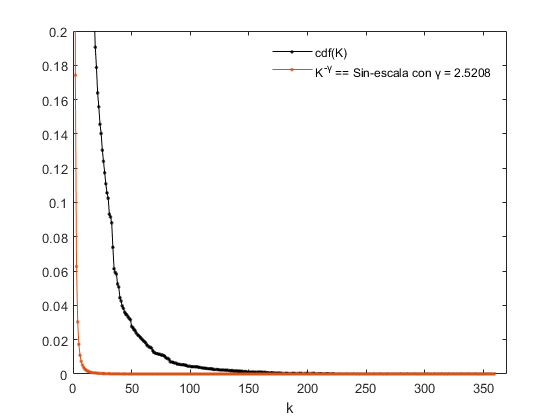


figure
plot(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k.-')
hold on
plot(1:max(grados_Colab_S),(1:max(grados_Colab_S)).^(-gamma_S),'.-')
xlabel('k')
axis([0 370 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(-reg(1))]},...
    'Location','northeast','Box','off');
hold off

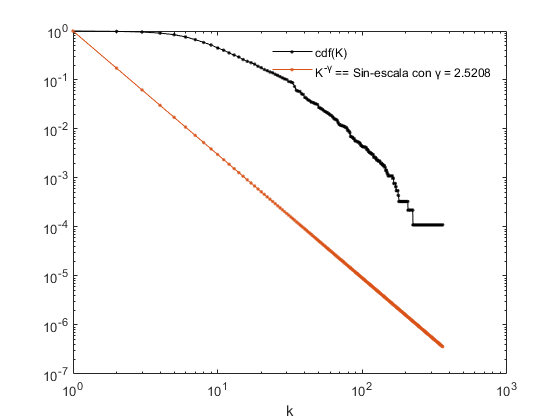


figure
loglog(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k.-')
hold on
loglog(1:max(grados_Colab_S),(1:max(grados_Colab_S)).^(-gamma_S),'.-')
xlabel('k')
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(-reg(1))]},...
    'Location','northeast','Box','off');
hold off

Con la funcion creada para sacar el gamma de la Super Matrix: 

scale_free_gamma(cdf_Colab_S_MAYOR,max(grados_Colab_S));

Ahora con cada uno de los paises

#### Alemania

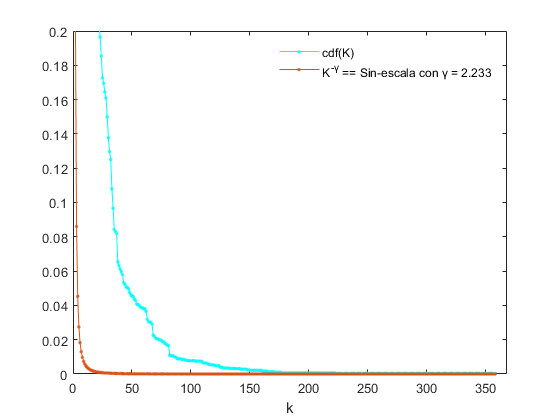

cdf_Colab_Ale_MAYOR = zeros(max(grados_Colab_A_S),1);
cdf_Colab_Ale_MAYOR(end) = DegDtbn_Colab_A_S(end);
for i = (length(DegDtbn_Colab_A_S)-1):-1:1
    cdf_Colab_Ale_MAYOR(i) = cdf_Colab_Ale_MAYOR(i+1) + DegDtbn_Colab_A_S(i);
end
[gamma_Ale, extra_Ale] = scale_free_gamma(cdf_Colab_Ale_MAYOR,max(grados_Colab_A_S));

figure
plot(1:max(grados_Colab_A_S),cdf_Colab_Ale_MAYOR,'c.-')
hold on
plot(1:max(grados_Colab_A_S),(1:max(grados_Colab_A_S)).^(-gamma_Ale),'.-')
xlabel('k')
axis([0 max(grados_Colab_A_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Ale)]},...
    'Location','northeast','Box','off');
hold off

#### Francia

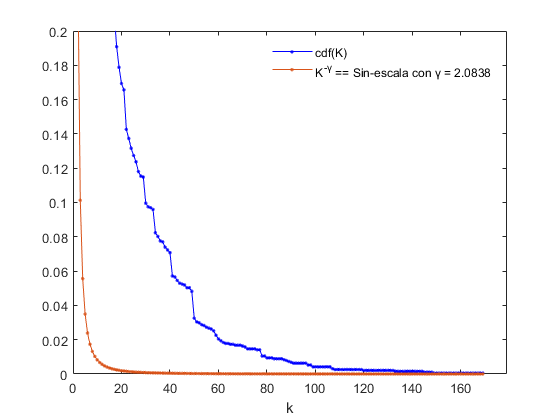

cdf_Colab_Fra_MAYOR = zeros(max(grados_Colab_F_S),1);
cdf_Colab_Fra_MAYOR(end) = DegDtbn_Colab_F_S(end);
for i = (length(DegDtbn_Colab_F_S)-1):-1:1
    cdf_Colab_Fra_MAYOR(i) = cdf_Colab_Fra_MAYOR(i+1) + DegDtbn_Colab_F_S(i);
end
[gamma_Fra, extra_Fra]  = scale_free_gamma(cdf_Colab_Fra_MAYOR,max(grados_Colab_F_S));

figure
plot(1:max(grados_Colab_F_S),cdf_Colab_Fra_MAYOR,'b.-')
hold on
plot(1:max(grados_Colab_F_S),(1:max(grados_Colab_F_S)).^(-gamma_Fra),'.-')
xlabel('k')
axis([0 max(grados_Colab_F_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Fra)]},...
    'Location','northeast','Box','off');
hold off

#### Italia

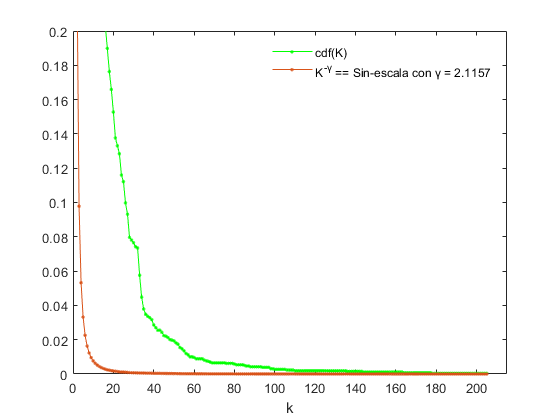

cdf_Colab_Ita_MAYOR = zeros(max(grados_Colab_I_S),1);
cdf_Colab_Ita_MAYOR(end) = DegDtbn_Colab_I_S(end);
for i = (length(DegDtbn_Colab_I_S)-1):-1:1
    cdf_Colab_Ita_MAYOR(i) = cdf_Colab_Ita_MAYOR(i+1) + DegDtbn_Colab_I_S(i);
end
[gamma_Ita, extra_Ita]  = scale_free_gamma(cdf_Colab_Ita_MAYOR,max(grados_Colab_I_S));

figure
plot(1:max(grados_Colab_I_S),cdf_Colab_Ita_MAYOR,'g.-')
hold on
plot(1:max(grados_Colab_I_S),(1:max(grados_Colab_I_S)).^(-gamma_Ita),'.-')
xlabel('k')
axis([0 max(grados_Colab_I_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Ita)]},...
    'Location','northeast','Box','off');
hold off

#### España

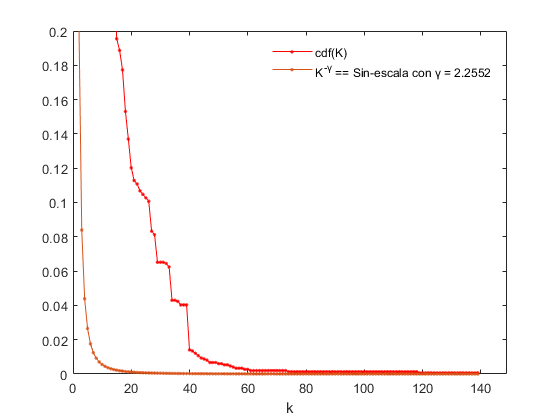

cdf_Colab_Esp_MAYOR = zeros(max(grados_Colab_E_S),1);
cdf_Colab_Esp_MAYOR(end) = DegDtbn_Colab_E_S(end);
for i = (length(DegDtbn_Colab_E_S)-1):-1:1
    cdf_Colab_Esp_MAYOR(i) = cdf_Colab_Esp_MAYOR(i+1) + DegDtbn_Colab_E_S(i);
end
[gamma_Esp, extra_Esp]  = scale_free_gamma(cdf_Colab_Esp_MAYOR,max(grados_Colab_E_S));

figure
plot(1:max(grados_Colab_E_S),cdf_Colab_Esp_MAYOR,'r.-')
hold on
plot(1:max(grados_Colab_E_S),(1:max(grados_Colab_E_S)).^(-gamma_Esp),'.-')
xlabel('k')
axis([0 max(grados_Colab_E_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Esp)]},...
    'Location','northeast','Box','off');
hold off

#### Portugal

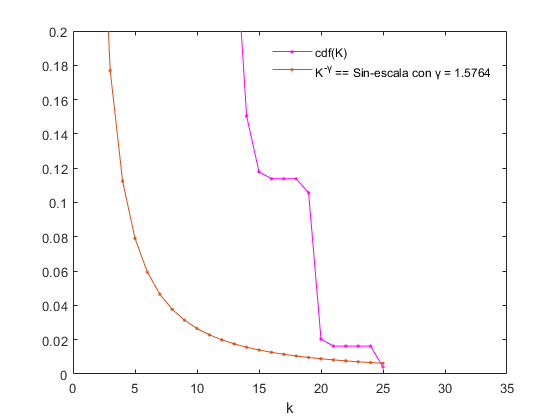

cdf_Colab_Por_MAYOR = zeros(max(grados_Colab_P_S),1);
cdf_Colab_Por_MAYOR(end) = DegDtbn_Colab_P_S(end);
for i = (length(DegDtbn_Colab_P_S)-1):-1:1
    cdf_Colab_Por_MAYOR(i) = cdf_Colab_Por_MAYOR(i+1) + DegDtbn_Colab_P_S(i);
end
[gamma_Por, extra_Por]  = scale_free_gamma(cdf_Colab_Por_MAYOR,max(grados_Colab_P_S));

figure
plot(1:max(grados_Colab_P_S),cdf_Colab_Por_MAYOR,'m.-')
hold on
plot(1:max(grados_Colab_P_S),(1:max(grados_Colab_P_S)).^(-gamma_Por),'.-')
xlabel('k')
axis([0 max(grados_Colab_P_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Por)]},...
    'Location','northeast','Box','off');
hold off

#### **GRAFICA DE LAS 6 JUNTAS EN UN SUBPLOT**

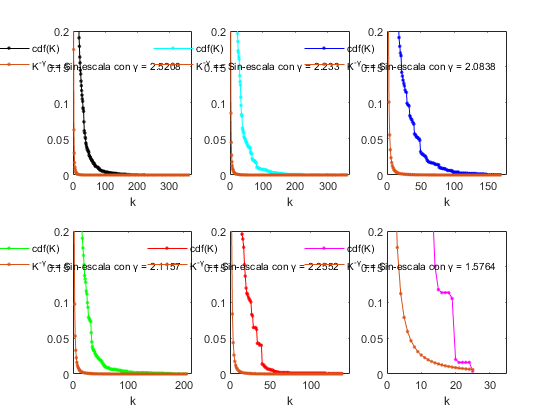

figure
subplot(2,3,1)
plot(1:max(grados_Colab_S),cdf_Colab_S_MAYOR,'k.-')
hold on
plot(1:max(grados_Colab_S),(1:max(grados_Colab_S)).^(-gamma_S),'.-')
xlabel('k')
axis([0 370 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(-reg(1))]},...
    'Location','northeast','Box','off');
hold off

subplot(2,3,2)
plot(1:max(grados_Colab_A_S),cdf_Colab_Ale_MAYOR,'c.-')
hold on
plot(1:max(grados_Colab_A_S),(1:max(grados_Colab_A_S)).^(-gamma_Ale),'.-')
xlabel('k')
axis([0 max(grados_Colab_A_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Ale)]},...
    'Location','northeast','Box','off');
hold off

subplot(2,3,3)
plot(1:max(grados_Colab_F_S),cdf_Colab_Fra_MAYOR,'b.-')
hold on
plot(1:max(grados_Colab_F_S),(1:max(grados_Colab_F_S)).^(-gamma_Fra),'.-')
xlabel('k')
axis([0 max(grados_Colab_F_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Fra)]},...
    'Location','northeast','Box','off');
hold off

subplot(2,3,4)
plot(1:max(grados_Colab_I_S),cdf_Colab_Ita_MAYOR,'g.-')
hold on
plot(1:max(grados_Colab_I_S),(1:max(grados_Colab_I_S)).^(-gamma_Ita),'.-')
xlabel('k')
axis([0 max(grados_Colab_I_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Ita)]},...
    'Location','northeast','Box','off');
hold off

subplot(2,3,5)
plot(1:max(grados_Colab_E_S),cdf_Colab_Esp_MAYOR,'r.-')
hold on
plot(1:max(grados_Colab_E_S),(1:max(grados_Colab_E_S)).^(-gamma_Esp),'.-')
xlabel('k')
axis([0 max(grados_Colab_E_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Esp)]},...
    'Location','northeast','Box','off');

subplot(2,3,6)
plot(1:max(grados_Colab_P_S),cdf_Colab_Por_MAYOR,'m.-')
hold on
plot(1:max(grados_Colab_P_S),(1:max(grados_Colab_P_S)).^(-gamma_Por),'.-')
xlabel('k')
axis([0 max(grados_Colab_P_S)+10 0 0.2])
legend({'cdf(K)',['K^{-γ} == Sin-escala con γ = ',num2str(gamma_Por)]},...
    'Location','northeast','Box','off');
hold off

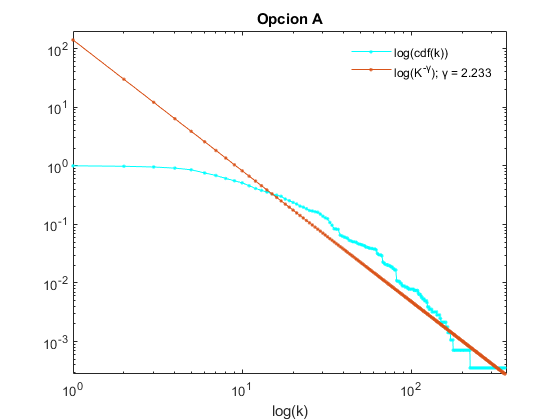

clf
figure
loglog(1:max(grados_Colab_A_S),cdf_Colab_Ale_MAYOR,'c.-')
hold on
loglog(1:max(grados_Colab_A_S),((1:max(grados_Colab_A_S)).^(-gamma_Ale))*10^extra_Ale,'.-')
xlabel('log(k)')
axis([0 max(grados_Colab_A_S)+10 0 200])
legend({'log(cdf(k))',['log(K^{-γ}); γ = ',num2str(gamma_Ale)]},...
    'Location','northeast','Box','off');
title('Opcion A')
hold off

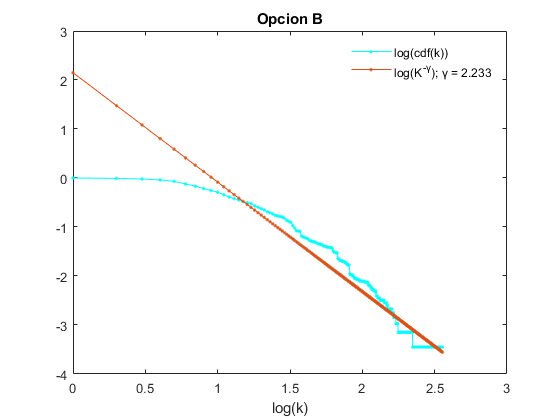

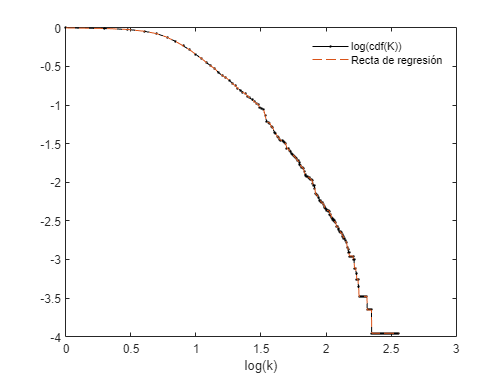


figure
plot(log10(1:max(grados_Colab_A_S)),log10(cdf_Colab_Ale_MAYOR),'c.-')
hold on
plot(log10(1:max(grados_Colab_A_S)),log10(((1:max(grados_Colab_A_S)).^(-gamma_Ale))*10^extra_Ale),'.-')
xlabel('log(k)')
legend({'log(cdf(k))',['log(K^{-γ}); γ = ',num2str(gamma_Ale)]},...
    'Location','northeast','Box','off');
title('Opcion B')
hold off

save("Variables_Arch_2_TFG.mat")

## **CENTRALIDAD**

## Medidas de centralidad

[V,D] = eigs(___) returns diagonal matrix D containing the eigenvalues on the main diagonal, and matrix V whose columns are the corresponding eigenvectors. You can use any of the input argument combinations in previous syntaxes. ***Default: Six largest magnitude eigenvalues of matrix A***

numero_eigenvalues = 8; %Numero de autovalores y autovectores para la siguiente funcion
[eigvec_Colab_S,eigval_Colab_S]=eigs(Colab_S,numero_eigenvalues);
disp(['Mayor Autovalor -> ',num2str(eigval_Colab_S(1,1))])

Mayor Autovalor -> 70.2109


### Eigenvector Centrality *Colab_S*

Denotamos ***lambda*** al mayor autovalor y ***lambda_vec*** a su autovector correspondiente.

[lambda_vec_Colab_S,lambda_Colab_S] = eigs(Colab_S,1);
Eigen_Centr_Node_Scores_Colab_S = lambda_vec_Colab_S;
Eigen_Centr_Node_Scores2_Colab_S = eigenvector_centrality_und(Colab_S); %Equivale a la anterior linea
Eigen_Centr_Network_Colab_S = mean(lambda_vec_Colab_S);
disp(['Eigenvector Centrality of the Network -> ',num2str(Eigen_Centr_Network_Colab_S)])

Eigenvector Centrality of the Network -> 0.0014317


Eigenvector centrality de manera que el maximo del autovector sea 1. (**Normalizado/Escalado del vector**) 

Scaled_Eigen_Centr_Node_Scores_Colab_S = Eigen_Centr_Node_Scores_Colab_S/max(Eigen_Centr_Node_Scores_Colab_S);
figure
plot(Scaled_Eigen_Centr_Node_Scores_Colab_S,':*b','LineWidth',0.2)
hold;

Current plot held


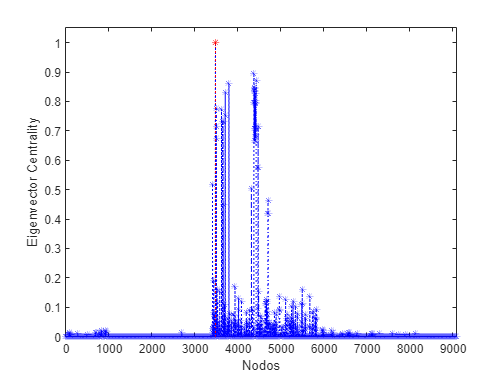

[ec_max, node_ec_max] = max(Scaled_Eigen_Centr_Node_Scores_Colab_S);
stem(node_ec_max, ec_max, ':*r','LineWidth',0.4)
axis([0 9088 0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality')

Vamos a detectar los 20 nodos mas importantes y los 20 menos importantes por el criterio del Eigenvector Centrality.

Unique da los valores unicos ordenados de menos a mayor y los mete en la matriz *C*, el vector *ia* determina cual es la posicion en el vector original del valor en la matriz *C*. Como *length(ia)~=length(ic)* hay ciertos valores repetidos pero suponemos que no estaran entre los *numero_nodos* primeros o los *numero_nodos* ultimos. De todas maneras esto se podria comprobar a mano. 

Por ejemplo, si el valor 0.24 esta en el 2ºindice de *C* quiere decir que el el 2º menor valor en el vector original. Y *ia(2) *sera la posicion en el vector original donde aparece por primera vez 0.24*, ia(2) *= 1068 y por tanto el nodo 1068 tiene el segundo valor mas bajo en el vector original. 

En *least_impotance* el orden de *ia* es el que queremos. Empieza por el menos importante.

En *most_importance* el orden de *ia* nos daria el "menos de los más importantes" por ello empleo **flip** para tenerlos ordenados empezando por el más importante de la red.

numero_nodos = 20;
[C,ia,ic] = unique(Eigen_Centr_Node_Scores_Colab_S);
least_importance_Colab_S = ia(1:numero_nodos)

least_importance_Colab_S =         5924
        5925
        2223
        2941
        5926
        2222
        1108
        1107
        2221
        2220


most_importance_Colab_S = flip(ia((length(ia)-numero_nodos+1):length(ia)))

most_importance_Colab_S =         3484
        4379
        4430
        3798
        4383
        4399
        4388
        4396
        3711
        4421


Visualizacion del eigenvector centrality y el nodo mas central:

clf
ec = eigenvector_centrality_und(Colab_S);
figure
plot(ec)
hold;

Current plot held


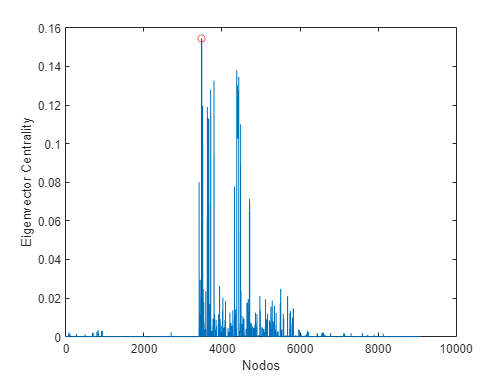

[ec_max, node_ec_max] = max(ec);
stem(node_ec_max, ec_max, 'or')
xlabel('Nodos')
ylabel('Eigenvector Centrality')

### Eigenvector Centrality *Fra_Colab*

ec_Fra = eigenvector_centrality_und(Fra_Colab);
[ec_Fra_max, node_ec_Fra_max] = max(ec_Fra);

Scaled_ec_Fra = ec_Fra/max(ec_Fra);
[max_value,max_node] = max(Scaled_ec_Fra); %max_node debe ser igual al node ec max y max_value=1

%Mayor autovalor
[lambda_vec_Fra_Colab,lambda_Fra_Colab] = eigs(Fra_Colab,1);

Resultados

disp(['Nodo mas central -> ',num2str(node_ec_Fra_max)])

Nodo mas central -> 93


disp(['Mayor Autovalor -> ',num2str(lambda_Fra_Colab)])

Mayor Autovalor -> 54.3577


numero_nodos = 10;
[C_F,ia_F,ic_F] = unique(ec_Fra);
least_importance_Fra_Colab = ia_F(1:numero_nodos)

least_importance_Fra_Colab =         1050
         734
        1816
        1424
        1183
         625
        1025
        1234
         719
         620


most_importance_Fra_Colab = flip(ia_F((length(ia_F)-numero_nodos+1):length(ia_F)))

most_importance_Fra_Colab =     93
   280
   798
   809
    85
   827
   800
   111
    94
   802


Grafica con eigenvector centrality escalada

figure
plot(Scaled_ec_Fra)
hold;

Current plot held


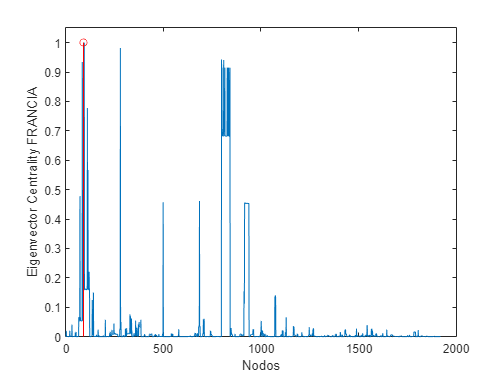

stem(max_node, max_value, 'or')
ylim([0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality FRANCIA')

### Eigenvector Centrality *Esp_Colab*

ec_Esp = eigenvector_centrality_und(Esp_Colab);
[ec_Esp_max, node_ec_Esp_max] = max(ec_Esp);

Scaled_ec_Esp = ec_Esp/max(ec_Esp);
[max_value,max_node] = max(Scaled_ec_Esp); %max_node debe ser igual al node ec max y max_value=1

%Mayor autovalor
[lambda_vec_Esp_Colab,lambda_Esp_Colab] = eigs(Esp_Colab,1);

Resultados

disp(['Nodo mas central -> ',num2str(node_ec_Esp_max)])

Nodo mas central -> 1180


disp(['Mayor Autovalor -> ',num2str(lambda_Esp_Colab)])

Mayor Autovalor -> 39.0028


numero_nodos = 10;
[C_E,ia_E,ic_E] = unique(ec_Esp);
least_importance_Esp_Colab = ia_E(1:numero_nodos)

least_importance_Esp_Colab =         1295
         797
         250
         883
         983
        1261
         830
         428
         934
         825


most_importance_Esp_Colab = flip(ia_E((length(ia_E)-numero_nodos+1):length(ia_E)))

most_importance_Esp_Colab =         1180
        1185
        1183
        1182
        1179
        1177
        1178
        1202
        1196
        1354


Grafica con eigenvector centrality escalada

figure
plot(Scaled_ec_Esp)
hold;

Current plot held


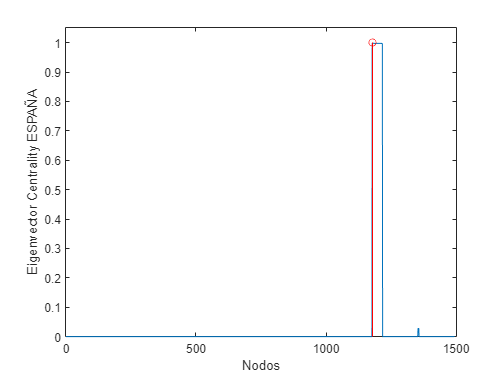

stem(max_node, max_value, 'or')
ylim([0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality ESPAÑA')

### Eigenvector Centrality *Ale_Colab*

ec_Ale = eigenvector_centrality_und(Ale_Colab);
[ec_Ale_max, node_ec_Ale_max] = max(ec_Ale);

Scaled_ec_Ale = ec_Ale/max(ec_Ale);
[max_value,max_node] = max(Scaled_ec_Ale); %max_node debe ser igual al node ec max y max_value=1

%Mayor autovalor
[lambda_vec_Ale_Colab,lambda_Ale_Colab] = eigs(Ale_Colab,1);

Resultados

disp(['Nodo mas central -> ',num2str(node_ec_Ale_max)])

Nodo mas central -> 71


disp(['Mayor Autovalor -> ',num2str(lambda_Ale_Colab)])

Mayor Autovalor -> 70.2012


numero_nodos = 10;
[C_A,ia_A,ic_A] = unique(ec_Ale);
least_importance_Ale_Colab = ia_A(1:numero_nodos)

least_importance_Ale_Colab =         1522
        1345
         889
         783
        1215
        1908
         553
         383
        2369
         631


most_importance_Ale_Colab = flip(ia_A((length(ia_A)-numero_nodos+1):length(ia_A)))

most_importance_Ale_Colab =           71
         966
        1017
         385
         970
         986
         975
         983
         298
        1008


Grafica con eigenvector centrality escalada

figure
plot(Scaled_ec_Ale)
hold;

Current plot held


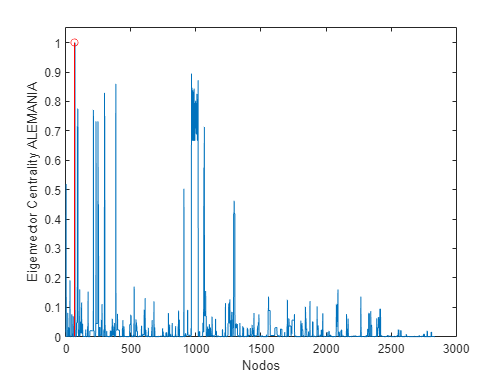

stem(max_node, max_value, 'or')
ylim([0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality ALEMANIA')

### Eigenvector Centrality *Ita_Colab*

ec_Ita = eigenvector_centrality_und(Ita_Colab);
[ec_Ita_max, node_ec_Ita_max] = max(ec_Ita);

ScItad_ec_Ita = ec_Ita/max(ec_Ita);
[max_value,max_node] = max(ScItad_ec_Ita); %max_node debe ser igual al node ec max y max_value=1

%Mayor autovalor
[lambda_vec_Ita_Colab,lambda_Ita_Colab] = eigs(Ita_Colab,1);

Resultados

disp(['Nodo mas central -> ',num2str(node_ec_Ita_max)])

Nodo mas central -> 145


disp(['Mayor Autovalor -> ',num2str(lambda_Ita_Colab)])

Mayor Autovalor -> 40.4443


numero_nodos = 10;
[C_I,ia_I,ic_I] = unique(ec_Ita);
least_importance_Ita_Colab = ia_I(1:numero_nodos)

least_importance_Ita_Colab =         2188
        1210
        1057
        1740
        2461
        1268
        2466
        1209
        1048
        1576


most_importance_Ita_Colab = flip(ia_I((length(ia_I)-numero_nodos+1):length(ia_I)))

most_importance_Ita_Colab =    145
   146
   114
   108
   153
     8
   386
   276
   862
   805


Grafica con eigenvector centrality escalada

figure
plot(ScItad_ec_Ita)
hold;

Current plot held


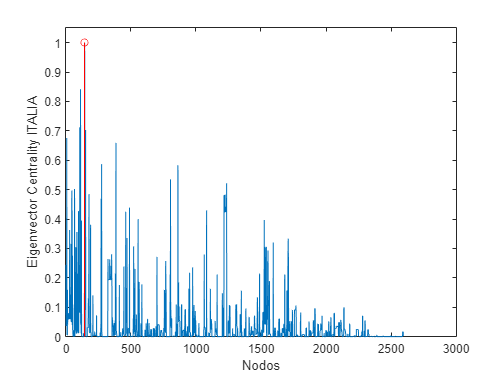

stem(max_node, max_value, 'or')
ylim([0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality ITALIA')

### Eigenvector Centrality *Por_Colab*

ec_Por = eigenvector_centrality_und_MOD(Por_Colab);
[ec_Por_max, node_ec_Por_max] = max(ec_Por);

ScPord_ec_Por = ec_Por/max(ec_Por);
[max_value,max_node] = max(ScPord_ec_Por); %max_node debe ser igual al node ec max y max_value=1

%Mayor autovalor
[lambda_vec_Por_Colab,lambda_Por_Colab] = eigs(Por_Colab,1);

Resultados

disp(['Nodo mas central -> ',num2str(node_ec_Por_max)])

Nodo mas central -> 38


disp(['Mayor Autovalor -> ',num2str(lambda_Por_Colab)])

Mayor Autovalor -> 19


numero_nodos = 10;
[C_P,ia_P,ic_P] = unique(ec_Por);
least_importance_Por_Colab = ia_P(1:numero_nodos)

least_importance_Por_Colab =    110
   109
   138
   142
   190
   191
   139
   141
   140
   166


most_importance_Por_Colab = flip(ia_P((length(ia_P)-numero_nodos+1):length(ia_P)))

most_importance_Por_Colab =     38
    43
    35
    34
    41
    48
   229
   235
   231
   227


Grafica con eigenvector centrality escalada

figure
plot(ScPord_ec_Por)
hold;

Current plot held


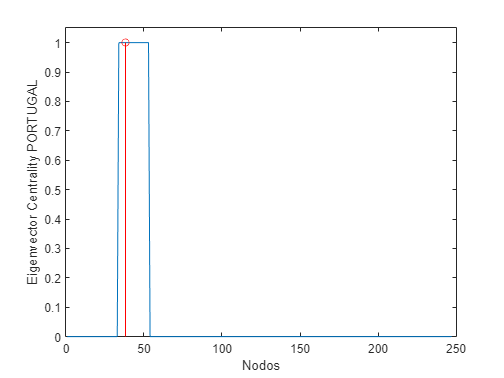

central_Ale = 71

central_Ita = 145

central_Fra = 93

central_Esp = 1180

central_Por = 38

links_GC_Ale =    (1,1)          19456


links_GC_Ita =    (1,1)          12547


links_GC_Fra =    (1,1)          11288


links_GC_Esp = 790

links_GC_Por = 190

D =    19.0000         0         0         0
         0   -1.0000         0         0
         0         0   -1.0000         0
         0         0         0   -1.0000


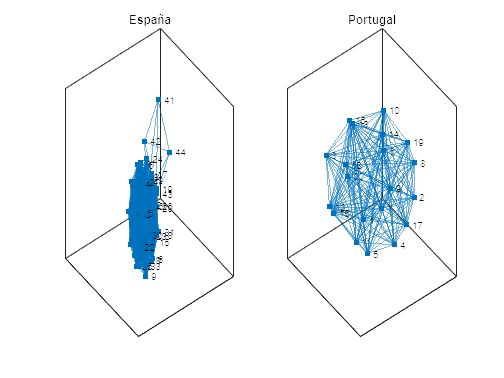

stem(max_node, max_value, 'or')
ylim([0 1.05])
xlabel('Nodos')
ylabel('Eigenvector Centrality PORTUGAL')

## **COMPONENTES GIGANTES DE CADA UNO DE LOS PAISES **

**Me apoyare en la funcion *****conncomp*****()**

Nodos de la componente gigante de **Alemania**

bins_Ale = conncomp(graph(Ale_Colab),'OutputForm','vector'); %nodos de todas las componentes
[~, ndsGC_Ale] = find(bins_Ale==1);    %nodos de la componente gigante se marcan con UNO (estos son los que sirven)

Nodos de la componente gigante de **Francia**

bins_Fra = conncomp(graph(Fra_Colab),'OutputForm','vector'); %nodos de todas las componentes
[~, ndsGC_Fra] = find(bins_Fra==1);    %nodos de la componente gigante se marcan con UNO (estos son los que sirven)

Nodos de la componente gigante de **Italia**

bins_Ita = conncomp(graph(Ita_Colab),'OutputForm','vector'); %nodos de todas las componentes
[~, ndsGC_Ita] = find(bins_Ita==1);    %nodos de la componente gigante se marcan con UNO (estos son los que sirven)

Nodos de la componente gigante de **España**

bins_Esp = conncomp(graph(Esp_Colab),'OutputForm','vector'); %nodos de todas las componentes
[~, ndsGC_Esp] = find(bins_Esp==1);    %nodos de la componente gigante se marcan con UNO (estos son los que sirven)

Nodos de la componente gigante de **Portugal**

bins_Por = conncomp(graph(Por_Colab),'OutputForm','vector'); %nodos de todas las componentes
[~, ndsGC_Por] = find(bins_Por==1);    %nodos de la componente gigante se marcan con UNO (estos son los que sirven)

Aplico la funcion [Giant_component](matlab:open('./Giant_component.m')) desarrollada por mi para obtener las componentes gigantes, el mayor autovalor, y los nodos centrales y perifericos de cada una de ellas

[adj_GC_A,Central_node_A,Peripheral_node_A,max_eigenvalue_1_A,max_eigenvalue_2_A] = Giant_component(Ale_Colab,ndsGC_Ale);
[adj_GC_I,Central_node_I,Peripheral_node_I,max_eigenvalue_1_I,max_eigenvalue_2_I] = Giant_component(Ita_Colab,ndsGC_Ita);
[adj_GC_F,Central_node_F,Peripheral_node_F,max_eigenvalue_1_F,max_eigenvalue_2_F] = Giant_component(Fra_Colab,ndsGC_Fra);
[adj_GC_E,Central_node_E,Peripheral_node_E,max_eigenvalue_1_E,max_eigenvalue_2_E] = Giant_component(Esp_Colab,ndsGC_Esp);
[adj_GC_P,Central_node_P,Peripheral_node_P,max_eigenvalue_1_P,max_eigenvalue_2_P] = Giant_component(Por_Colab,ndsGC_Por);

Numero de links de cada componente gigante

links_GC_Ale = sum(sum(adj_GC_A))/2

links_GC_Ale =    (1,1)          19456


links_GC_Ita = sum(sum(adj_GC_I))/2

links_GC_Ita =    (1,1)          12547


links_GC_Fra = sum(sum(adj_GC_F))/2

links_GC_Fra =    (1,1)          11288


links_GC_Esp = sum(sum(adj_GC_E))/2

links_GC_Esp = 4525

links_GC_Por = sum(sum(adj_GC_P))/2

links_GC_Por = 273

Numero de links de cada pais (Su matriz completa de país)

links_Ale = sum(sum(Ale_Colab))/2

links_Ale =    (1,1)          22159


links_Ita = sum(sum(Ita_Colab))/2

links_Ita =    (1,1)          15720


links_Fra = sum(sum(Fra_Colab))/2

links_Fra =    (1,1)          13198


links_Esp = sum(sum(Esp_Colab))/2

links_Esp =    (1,1)           8175


links_Por = sum(sum(Por_Colab))/2

links_Por =    (1,1)           1119


### REPRESENTACION DE LOS GRAFOS DE LAS COMPONENTES GIGANTES

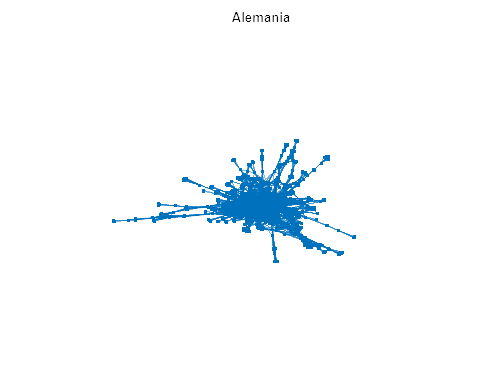

clf 
G = graph(adj_GC_A);
plot(G, 'Layout', 'force3')
axis off
title('Alemania')

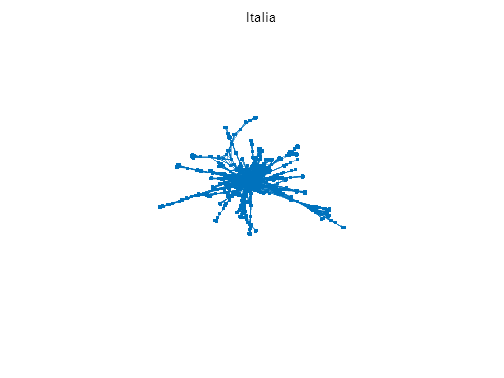


G = graph(adj_GC_I);
plot(G, 'Layout', 'force3')
axis off
title('Italia')

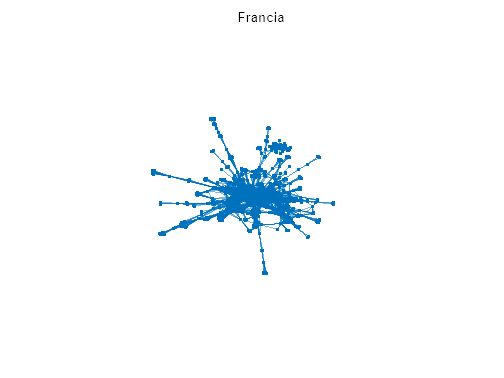


G = graph(adj_GC_F);
plot(G, 'Layout', 'force3')
axis off
title('Francia')

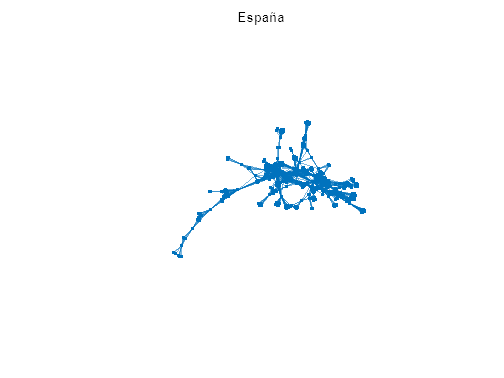


G = graph(adj_GC_E);
plot(G, 'Layout', 'force3')
axis off
title('España')

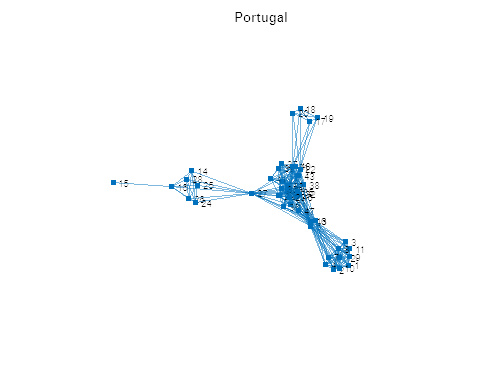


G = graph(adj_GC_P);
plot(G, 'Layout', 'force3')
axis off
title('Portugal')

Face to Face de CG de Portugal y de España

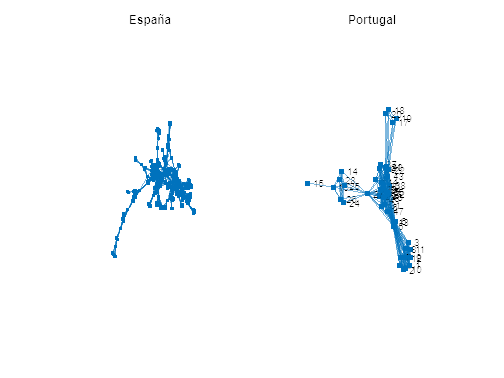

figure
subplot(1,2,1)
G = graph(adj_GC_E);
plot(G, 'Layout', 'force3')
axis off
title('España')
subplot(1,2,2)
G = graph(adj_GC_P);
plot(G, 'Layout', 'force3')
axis off
title('Portugal')

#### Guardo en .txt los nodos y  las componentes gigantes para poder usarlos en otros archivos

nodes_GC_Ale = ndsGC_Ale; nodes_GC_Fra = ndsGC_Fra; nodes_GC_Esp = ndsGC_Esp; nodes_GC_Ita = ndsGC_Ita; nodes_GC_Por = ndsGC_Por;
save("Nodos.mat" ,'nodes_GC_Ale','nodes_GC_Fra','nodes_GC_Esp','nodes_GC_Ita','nodes_GC_Por')
save("Data_CGs.mat",'adj_GC_A','adj_GC_F','adj_GC_I','adj_GC_E','adj_GC_P',...
    'Central_node_A','Central_node_F','Central_node_I','Central_node_E','Central_node_P',...
    'Peripheral_node_A','Peripheral_node_I','Peripheral_node_F','Peripheral_node_E','Peripheral_node_P',...
    'max_eigenvalue_1_A','max_eigenvalue_1_F','max_eigenvalue_1_I','max_eigenvalue_1_E','max_eigenvalue_1_P',...
    'max_eigenvalue_2_A','max_eigenvalue_2_F','max_eigenvalue_2_I','max_eigenvalue_2_E','max_eigenvalue_2_P')

#### Guardo en .txt las componentes gigantes

writematrix(adj_GC_A,'adj_GC_A','Delimiter',' ')
writematrix(adj_GC_F,'adj_GC_F','Delimiter',' ')
writematrix(adj_GC_I,'adj_GC_I','Delimiter',' ')
writematrix(adj_GC_E,'adj_GC_E','Delimiter',' ')
writematrix(adj_GC_P,'adj_GC_P','Delimiter',' ')